# MAGEMin Equilibrium Path Calculator

Use MAGEMin to calculate stable phase equilibria along $P$,$T$-path at a given bulk composition.

clear all; close all;
addpath('./matlab');

## Specify run mode

Select from the following run modes: 

### **Closed system**

Calculate phase equilibria along a set $P,T$-path and constant bulk composition.

### **Fractionation**

Calculate phase equilibria along a set $P,T$-path where at each step all solid phases are discarded up to a set residual fraction.

### **Assimilation**

Calculate phase equilibria along a set $P,T$-path where at each step a set fraction of an assimilant is added to the bulk composition.

### **Fractionation / assimilation**

Calculate phase equilibria along a set $P,T$-path where at each step all solid phases are discarded up to a set residual fraction, and a set fraction of an assimilant is added.

RunMode = 'fractionation/assimilation';

## Specify starting composition

Enter starting bulk composition either in wt % of oxides, water, and excess oxygen. The oxidation state is set based on the entered fraction of excess oxygen (O). Select predefined compositions (see documentation) from drop-down menu or select `none` and manually set values in the table below. Note that values will be normalised to 100% sum.

% Specify starting composition
OxdNames      = {'SiO2','Al2O3','CaO','MgO','FeOt','K2O','Na2O','TiO2','O','Cr2O3','H2O'};

% Select predefined composition 0-8, (leave on -1 to manually specify composition in table below
Chemistry.Predefined = nan;     % predefined compositions 
Chemistry.sys_in     = 'mol';                  % predefined in mol %

if isnan(Chemistry.Predefined)
    Chemistry.sys_in     = 'wt';                  % predefined in mol %

    OxideFractions( 1) = 51.3122;  % SiO2
    OxideFractions( 8) = 1.7841;  % TiO2
    OxideFractions( 2) = 13.812;  % Al2O3
    OxideFractions(10) = 0.209;  % Cr2O3
    OxideFractions( 5) = 10.7646;  % FeOt
    OxideFractions( 4) = 6.0394;  % MgO
    OxideFractions( 3) = 11.312;  % CaO
    OxideFractions( 7) = 2.1487;  % Na2O
    OxideFractions( 6) = 0.3637;  % K2O
    OxideFractions(11) = 0;  % H2O
    OxideFractions( 9) = 0.25;  % O
    OxideFractions     =  OxideFractions./sum(OxideFractions).*100;
    Chemistry.OxProp   =  table(OxdNames(:),OxideFractions(:),'VariableNames',{'Oxide','wt %'});
end

## Specify $P,T$-Path

% Specify P,T path
P_max  =  1;  % maximum pressure [kbar]
P_min  =  1;  % minimum pressure [kbar]
P_stp  =  0;  % incrmnt pressure [kbar]

T_max  =  1200;  % maximum pressure [kbar]
T_min  =  900;  % minimum pressure [kbar]
T_stp  =  25;  % incrmnt pressure [kbar]

if ~P_stp || ~(P_max-P_min)  % isobaric path
    T_vec      =  (T_max:-T_stp:T_min).';
    P_vec      =   P_max.*ones(size(T_vec));
    isobaric   =  true;
    isothermal =  false;
    pathlbl    =  'isobaric';
elseif ~T_stp || ~(T_max-T_min)  % isothermal path
    P_vec      =  (P_max:-P_stp:P_min).';
    T_vec      =   T_max.*ones(size(P_vec));
    isothermal =  true;
    isobaric   =  false;
    pathlbl    =  'isothermal';
else
    nstp       =  max(round((P_max-P_min)/P_stp),round((T_max-T_min)/T_stp));
    P_vec      =  linspace(P_max,P_min,nstp).';
    T_vec      =  linspace(T_max,T_min,nstp).';
    isothermal =  false;
    isobaric   =  false;
    pathlbl    =  'PT';
end
TP_vec  = [T_vec,P_vec];
Points  =  1:size(T_vec,1);

## Specify open system parameters

If run mode is set to fractionation, assimilation, or combined fractionation/assimilation, set the retained residual solid fraction, the fraction of assimilant added, and assimilant composition in wt% (values will be normalised to 100% sum).

% Specify retained solid fraction
retain_fract = 0.05;

% Specify added assimilant fraction
assml_fract = 0.1;

% Specify assimilant composition
AssmlOxideFractions( 1) = 65.3122;  % SiO2
AssmlOxideFractions( 8) = 1.7841;  % TiO2
AssmlOxideFractions( 2) = 15.812;  % Al2O3
AssmlOxideFractions(10) = 0.209;  % Cr2O3
AssmlOxideFractions( 5) = 6.7646;  % FeOt
AssmlOxideFractions( 4) = 4.0394;  % MgO
AssmlOxideFractions( 3) = 9.312;  % CaO
AssmlOxideFractions( 7) = 3.1487;  % Na2O
AssmlOxideFractions( 6) = 1.3637;  % K2O
AssmlOxideFractions(11) = 0;  % H2O
AssmlOxideFractions( 9) = 0.25;  % O
AssmlOxideFractions     =  AssmlOxideFractions./sum(AssmlOxideFractions).*100;

## Run calculation

Select number of processors and enter directory where `mpich` parallel executable `mpiexec` is found to run calculations in parallel. Select single processor to run in serial mode, which is normally sufficient. See documentation about installation steps for parallel functionality. 

% Set parallel run options
Computation.NumRanks   = 1;        % # of processors if we compute in parallel
Computation.MPI_dir    = "/usr/local/bin";  % directory that has the MPI executable

% Set default values for computation
VerboseLevel                      = 0;        % set to create thermocalc-style output file
Computation.RefinementLevels      = 1;        % # of refinement levels
Computation.Verbose               = 0;        % How much info will be shown?
Computation.AllPoints             = 1;        % Do we compute with all points or not?
Computation.UseGammaEstimation    = 0;        % Use previous gamma or not?
Computation.RemoteServer          = false;    % perform all computations on a remote server?
Computation.MinPhaseFraction      = 3e-3;     % Minimum require phase fraction, before we take a phase into account
Computation.num_Neighbours        = 9;
Computation.Use_xEOS              = false;
Computation.Use_EMFrac            = false;
Computation.EOS_Method            = 'Average surrounding points';
Computation.MatlabOut             = 1;        % set output style to retrieve data

% Determine if we use the BinaryBuilder/Julia binary or a locally compiled version of MAGEMin.
path_dylib=[];
path_bin=[];
path_julia=[];
if exist('environmental_variables','file')==2
    % yes, we did run the julia installation script @ some stage
    Computation.Julia_MAGEMin_binary  =   true;

    environmental_variables;                                    % run script

    Computation.path_dylib    = path_dylib;   % dynamic libraries
    Computation.path_bin      = path_bin;     % MAGEMin & mpiexec binaries
else
    Computation.Julia_MAGEMin_binary = false;
end

% Check if a local MAGEMin version is available
if exist('MAGEMin')==2 || exist('MAGEMin.exe')==2
    Computation.Local_MAGEMin_binary = true;
else
    Computation.Local_MAGEMin_binary = false;
end

% set binary toggle
if      Computation.Julia_MAGEMin_binary==true && Computation.Local_MAGEMin_binary==true
    Computation.BinaryMethod = 'Local';
elseif  Computation.Julia_MAGEMin_binary==true && Computation.Local_MAGEMin_binary==false
    Computation.BinaryMethod = 'Default';
elseif  Computation.Julia_MAGEMin_binary==false && Computation.Local_MAGEMin_binary==true
    Computation.BinaryMethod = 'Local';
else
    % No binary is available at all; switch color of button to
    % red
    app.Binary_Switch.FontColor=[1,0,0];
    Computation.BinaryMethod = 'none';

    % Call installation GUI
    app_install = Install_MAGEMin;
    while isvalid(app_install); pause(0.1); end

end

% retrieve version number of executable
if Computation.Julia_MAGEMin_binary==true || Computation.Local_MAGEMin_binary==true
    exe = MAGEMin_exe(Computation);

    command = [exe,' --version'];
    if Computation.Local_MAGEMin_binary==false
        command = add_dynamic_libs(command, Computation);
    end
    [stat, cmdout] = system(command);
    disp(cmdout)
    A=[];A=split(cmdout);
    MAGEMin_Version = A(2);

end

MAGEMin   1.2.3 [15/08/2022]




ComputeAllPoints    = true;
dlg.CancelRequested = false;

% run MAGEMin calculations
disp(['Running MAGEMin along ',pathlbl,' path in ',RunMode,' mode.']);

Running MAGEMin along isobaric path in fractionation/assimilation mode.



switch RunMode
    case 'closed system' % equilibrium path
        [OUT, ~, ~, ~] = PerformMAGEMin_Simulation([], Points, TP_vec, VerboseLevel, Chemistry, dlg, ComputeAllPoints, false, Computation);
    
    otherwise 
        for ip = Points
            [OUTP, ~, ~, ~] = PerformMAGEMin_Simulation([], 1, TP_vec(ip,:), VerboseLevel, Chemistry, dlg, ComputeAllPoints, false, Computation);
            
            OUT.numStablePhases(ip)   =  length(OUTP.StablePhases);
            OUT.StablePhases(ip,1:length(OUTP.StablePhases))  =  OUTP.StablePhases;
            OUT.StableSolutions(ip,1:length(OUTP.StableSolutions))  =  OUTP.StableSolutions;
            OUT.StablePurePhases(ip,1:length(OUTP.StablePurePhases))  =  OUTP.StablePurePhases;
            OUT.P(ip)                 =  OUTP.P;
            OUT.T(ip)                 =  OUTP.T;
            OUT.OxideList(ip,:)       =  OUTP.OxideList;
            OUT.PhasePropsList(ip,:)  =  OUTP.PhasePropsList;
            OUT.SYSPropsList(ip,:)    =  OUTP.SYSPropsList;
            OUT.SYSProps(ip,:)        =  OUTP.SYSProps;
            OUT.GammaList(ip,:)       =  OUTP.GammaList;
            OUT.Gamma(ip,:)           =  OUTP.Gamma;
            OUT.DeltaGibbsList(ip,1:length(OUTP.StableSolutions))  =  OUTP.StableSolutions;
            OUT.DeltaGibbs(ip,1:length(OUTP.StableSolutions))      =  OUTP.DeltaGibbs;

            flds = fieldnames(OUTP.PhaseFractions    ); for ifld = 1:length(flds); OUT.PhaseFractions    .(flds{ifld})(ip,:)  =  OUTP.PhaseFractions    .(flds{ifld}); end
            flds = fieldnames(OUTP.Density           ); for ifld = 1:length(flds); OUT.Density           .(flds{ifld})(ip,:)  =  OUTP.Density           .(flds{ifld}); end
            flds = fieldnames(OUTP.Viscosity         ); for ifld = 1:length(flds); OUT.Viscosity         .(flds{ifld})(ip,:)  =  OUTP.Viscosity         .(flds{ifld}); end
            flds = fieldnames(OUTP.EMList            ); for ifld = 1:length(flds); OUT.EMList            .(flds{ifld})(ip,:)  =  OUTP.EMList            .(flds{ifld}); end
            flds = fieldnames(OUTP.EMFractions       ); for ifld = 1:length(flds); OUT.EMFractions       .(flds{ifld})(ip,:)  =  OUTP.EMFractions       .(flds{ifld}); end
            flds = fieldnames(OUTP.SiteFractions     ); for ifld = 1:length(flds); OUT.SiteFractions     .(flds{ifld})(ip,:)  =  OUTP.SiteFractions     .(flds{ifld}); end
            flds = fieldnames(OUTP.OxideFractions    ); for ifld = 1:length(flds); OUT.OxideFractions    .(flds{ifld})(ip,:)  =  OUTP.OxideFractions    .(flds{ifld}); end
            flds = fieldnames(OUTP.OxideFractions_mol); for ifld = 1:length(flds); OUT.OxideFractions_mol.(flds{ifld})(ip,:)  =  OUTP.OxideFractions_mol.(flds{ifld}); end
            flds = fieldnames(OUTP.PhaseProps        ); for ifld = 1:length(flds); OUT.PhaseProps        .(flds{ifld})(ip,:)  =  OUTP.PhaseProps        .(flds{ifld}); end

            if OUTP.PhaseFractions.sol_wt>1e-6 && OUTP.PhaseFractions.sol_wt<1-1e-6
                switch RunMode
                    case 'fractionation'
                        OxideFractions  =  (OUTP.PhaseFractions.liq_wt.*OUTP.OxideFractions.liq + min(OUTP.PhaseFractions.sol_wt,retain_fract).*OUTP.OxideFractions.sol)./(OUTP.PhaseFractions.liq_wt+min(OUTP.PhaseFractions.sol_wt,retain_fract));
                        OxideFractions  =  OxideFractions./sum(OxideFractions).*100;
                    case 'assimilation'
                        OxideFractions  =  (1-assml_fract).*OxideFractions + assml_fract.*AssmlOxideFractions;
                        OxideFractions  =  OxideFractions./sum(OxideFractions).*100;
                    case 'fractionation/assimilation'
                        OxideFractions  =  (OUTP.PhaseFractions.liq_wt.*OUTP.OxideFractions.liq + min(OUTP.PhaseFractions.sol_wt,retain_fract).*OUTP.OxideFractions.sol)./(OUTP.PhaseFractions.liq_wt+min(OUTP.PhaseFractions.sol_wt,retain_fract));
                        OxideFractions  =  OxideFractions./sum(OxideFractions).*100;
                        OxideFractions  =  (1-assml_fract).*OxideFractions + assml_fract.*AssmlOxideFractions;
                        OxideFractions  =  OxideFractions./sum(OxideFractions).*100;
                end
                Chemistry.OxProp   =  table(OxdNames(:),OxideFractions(:),'VariableNames',{'Oxide','wt %'});
            end
        end
end

zsh:1: no matches found: _pseudosection_output.*.*
./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=52.3617,14.0945,11.5434,6.1629,10.9848,0.37114,2.1926,1.8206,0.25511,0.21327,0,


command = 'export PATH=/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/bin:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/bin ;  export DYLD_LIBRARY_PATH=/Users/tokeller/.julia/artifacts/3de79395eef7694a5f90e9feb05eb575a59e69ae/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/lib/julia:/Users/tokeller/.julia/artifacts/c5444803422dfcb90ced251156d1d4e0188432d0/lib:/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/lib:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib/julia:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib; ./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=52.3617,14.0945,11.5434,6.1629,10.9848,0.37114,2.1926,1.8206,0.25511,0.21327,0,'

No matching processes belonging to you were found


ans = 1


Running MAGEMin 1.2.3 [15/08/2022] on 1 cores {
═══════════════════════════════════════════════
 Status             :            0 
 Mass residual      : +6.11181e-06
 Rank               :            0 
 Point              :            0 
 Temperature        :  +1200.00000	 [C] 
 Pressure           :     +1.00000	 [kbar]

 SOL = [G: -998.228] (40 iterations, 122.15 ms)
 GAM = [-1047.194085,-1897.644470,-849.257136,-724.024921,-440.647167,-1111.428740,-971.055045,-1101.082280,-271.787386,-1418.196529]

 Phase :      liq      spn 
 Mode  :  0.99987  0.00017 
___________________________________
MAGEMin comp time: +133.044000 ms }


ForwardSimulation_Time = 0.3201

ReadData_Time = 0.0511

zsh:1: no matches found: _pseudosection_output.*.*
./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=53.1761,14.1481,11.2504,5.9184,10.5157,0.4601,2.2648,1.8037,0.25288,0.2098,0,


command = 'export PATH=/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/bin:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/bin ;  export DYLD_LIBRARY_PATH=/Users/tokeller/.julia/artifacts/3de79395eef7694a5f90e9feb05eb575a59e69ae/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/lib/julia:/Users/tokeller/.julia/artifacts/c5444803422dfcb90ced251156d1d4e0188432d0/lib:/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/lib:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib/julia:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib; ./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=53.1761,14.1481,11.2504,5.9184,10.5157,0.4601,2.2648,1.8037,0.25288,0.2098,0,'

No matching processes belonging to you were found


ans = 1


Running MAGEMin 1.2.3 [15/08/2022] on 1 cores {
═══════════════════════════════════════════════
 Status             :            0 
 Mass residual      : +9.32566e-06
 Rank               :            0 
 Point              :            0 
 Temperature        :  +1175.00000	 [C] 
 Pressure           :     +1.00000	 [kbar]

 SOL = [G: -998.669] (66 iterations, 163.32 ms)
 GAM = [-1043.130203,-1892.855486,-845.950097,-720.754800,-435.825719,-1096.363336,-962.515988,-1095.324750,-270.156484,-1412.789578]

 Phase :      spn     pl4T      liq 
 Mode  :  0.00080  0.05148  0.94769 
___________________________________
MAGEMin comp time: +175.171000 ms }


ForwardSimulation_Time = 0.2780

ReadData_Time = 0.0256

zsh:1: no matches found: _pseudosection_output.*.*
./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=53.9044,14.1858,10.9858,5.6889,10.1182,0.54039,2.3294,1.7889,0.25043,0.20793,0,


command = 'export PATH=/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/bin:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/bin ;  export DYLD_LIBRARY_PATH=/Users/tokeller/.julia/artifacts/3de79395eef7694a5f90e9feb05eb575a59e69ae/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/lib/julia:/Users/tokeller/.julia/artifacts/c5444803422dfcb90ced251156d1d4e0188432d0/lib:/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/lib:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib/julia:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib; ./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=53.9044,14.1858,10.9858,5.6889,10.1182,0.54039,2.3294,1.7889,0.25043,0.20793,0,'

No matching processes belonging to you were found


ans = 1


Running MAGEMin 1.2.3 [15/08/2022] on 1 cores {
═══════════════════════════════════════════════
 Status             :            0 
 Mass residual      : +9.62470e-06
 Rank               :            0 
 Point              :            0 
 Temperature        :  +1150.00000	 [C] 
 Pressure           :     +1.00000	 [kbar]

 SOL = [G: -998.581] (60 iterations, 181.89 ms)
 GAM = [-1039.106722,-1888.363687,-842.513925,-717.618690,-431.067177,-1082.444724,-954.032465,-1090.349276,-268.684375,-1407.507825]

 Phase :      liq     pl4T      spn      spn 
 Mode  :  0.89456  0.10095  0.00308  0.00134 
___________________________________
MAGEMin comp time: +192.476000 ms }


ForwardSimulation_Time = 0.2618

ReadData_Time = 0.0169

zsh:1: no matches found: _pseudosection_output.*.*
./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=54.9486,13.3676,10.5443,5.7108,10.1691,0.63906,2.3851,1.804,0.25765,0.17378,0,


command = 'export PATH=/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/bin:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/bin ;  export DYLD_LIBRARY_PATH=/Users/tokeller/.julia/artifacts/3de79395eef7694a5f90e9feb05eb575a59e69ae/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/lib/julia:/Users/tokeller/.julia/artifacts/c5444803422dfcb90ced251156d1d4e0188432d0/lib:/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/lib:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib/julia:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib; ./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=54.9486,13.3676,10.5443,5.7108,10.1691,0.63906,2.3851,1.804,0.25765,0.17378,0,'

No matching processes belonging to you were found


ans = 1


Running MAGEMin 1.2.3 [15/08/2022] on 1 cores {
═══════════════════════════════════════════════
 Status             :            0 
 Mass residual      : +9.42864e-06
 Rank               :            0 
 Point              :            0 
 Temperature        :  +1125.00000	 [C] 
 Pressure           :     +1.00000	 [kbar]

 SOL = [G: -990.725] (42 iterations, 154.62 ms)
 GAM = [-1034.898979,-1883.766010,-839.965275,-715.474160,-425.956195,-1068.712606,-945.978166,-1087.075369,-266.975618,-1403.070750]

 Phase :      liq     pl4T      cpx      spn      spn 
 Mode  :  0.81093  0.12932  0.04440  0.01407  0.00078 
___________________________________
MAGEMin comp time: +165.557000 ms }


ForwardSimulation_Time = 0.2325

ReadData_Time = 0.0110

zsh:1: no matches found: _pseudosection_output.*.*
./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=56.8515,12.2328,9.788,5.4433,10.4357,0.7897,2.474,1.5886,0.26647,0.12981,0,


command = 'export PATH=/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/bin:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/bin ;  export DYLD_LIBRARY_PATH=/Users/tokeller/.julia/artifacts/3de79395eef7694a5f90e9feb05eb575a59e69ae/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/lib/julia:/Users/tokeller/.julia/artifacts/c5444803422dfcb90ced251156d1d4e0188432d0/lib:/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/lib:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib/julia:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib; ./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=56.8515,12.2328,9.788,5.4433,10.4357,0.7897,2.474,1.5886,0.26647,0.12981,0,'

No matching processes belonging to you were found


ans = 1


Running MAGEMin 1.2.3 [15/08/2022] on 1 cores {
═══════════════════════════════════════════════
 Status             :            0 
 Mass residual      : +7.96139e-06
 Rank               :            0 
 Point              :            0 
 Temperature        :  +1100.00000	 [C] 
 Pressure           :     +1.00000	 [kbar]

 SOL = [G: -982.103] (33 iterations, 380.16 ms)
 GAM = [-1030.647355,-1878.714785,-838.307707,-713.957999,-420.760680,-1056.088515,-938.942033,-1083.735573,-265.393199,-1399.812125]

 Phase :      liq     pl4T      spn      cpx      spn 
 Mode  :  0.76559  0.12998  0.01738  0.08670  0.00009 
___________________________________
MAGEMin comp time: +391.202000 ms }


ForwardSimulation_Time = 0.4696

ReadData_Time = 0.0271

zsh:1: no matches found: _pseudosection_output.*.*
./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=59.2561,11.4003,8.741,4.8147,10.5533,0.99048,2.5696,1.3096,0.26871,0.096315,0,


command = 'export PATH=/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/bin:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/bin ;  export DYLD_LIBRARY_PATH=/Users/tokeller/.julia/artifacts/3de79395eef7694a5f90e9feb05eb575a59e69ae/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/lib/julia:/Users/tokeller/.julia/artifacts/c5444803422dfcb90ced251156d1d4e0188432d0/lib:/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/lib:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib/julia:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib; ./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=59.2561,11.4003,8.741,4.8147,10.5533,0.99048,2.5696,1.3096,0.26871,0.096315,0,'

No matching processes belonging to you were found


ans = 1


Running MAGEMin 1.2.3 [15/08/2022] on 1 cores {
═══════════════════════════════════════════════
 Status             :            0 
 Mass residual      : +6.87946e-06
 Rank               :            0 
 Point              :            0 
 Temperature        :  +1075.00000	 [C] 
 Pressure           :     +1.00000	 [kbar]

 SOL = [G: -978.267] (30 iterations, 378.68 ms)
 GAM = [-1026.496262,-1873.692923,-836.573463,-712.429423,-415.907335,-1044.596453,-932.565048,-1080.561326,-264.444948,-1398.794674]

 Phase :      liq      spn      cpx     pl4T      opx 
 Mode  :  0.76865  0.01744  0.09032  0.12315  0.00045 
___________________________________
MAGEMin comp time: +389.582000 ms }


ForwardSimulation_Time = 0.4537

ReadData_Time = 0.0101

zsh:1: no matches found: _pseudosection_output.*.*
./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=61.7896,10.7729,7.7596,4.1885,10.2794,1.2048,2.6168,1.0614,0.25655,0.070386,0,


command = 'export PATH=/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/bin:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/bin ;  export DYLD_LIBRARY_PATH=/Users/tokeller/.julia/artifacts/3de79395eef7694a5f90e9feb05eb575a59e69ae/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/lib/julia:/Users/tokeller/.julia/artifacts/c5444803422dfcb90ced251156d1d4e0188432d0/lib:/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/lib:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib/julia:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib; ./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=61.7896,10.7729,7.7596,4.1885,10.2794,1.2048,2.6168,1.0614,0.25655,0.070386,0,'

No matching processes belonging to you were found


ans = 1


Running MAGEMin 1.2.3 [15/08/2022] on 1 cores {
═══════════════════════════════════════════════
 Status             :            0 
 Mass residual      : +1.60448e-06
 Rank               :            0 
 Point              :            0 
 Temperature        :  +1050.00000	 [C] 
 Pressure           :     +1.00000	 [kbar]

 SOL = [G: -977.867] (25 iterations, 129.46 ms)
 GAM = [-1022.440388,-1868.944081,-834.486543,-711.093552,-411.417029,-1033.722867,-926.501100,-1076.954921,-264.240340,-1399.324427]

 Phase :     pl4T      liq      cpx      spn      opx 
 Mode  :  0.12233  0.76993  0.08234  0.01681  0.00861 
___________________________________
MAGEMin comp time: +140.860000 ms }


ForwardSimulation_Time = 0.2049

ReadData_Time = 0.0066

zsh:1: no matches found: _pseudosection_output.*.*
./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=64.4366,10.3064,6.8972,3.545,9.5569,1.4232,2.6838,0.86967,0.22881,0.05249,0,


command = 'export PATH=/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/bin:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/bin ;  export DYLD_LIBRARY_PATH=/Users/tokeller/.julia/artifacts/3de79395eef7694a5f90e9feb05eb575a59e69ae/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/lib/julia:/Users/tokeller/.julia/artifacts/c5444803422dfcb90ced251156d1d4e0188432d0/lib:/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/lib:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib/julia:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib; ./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=64.4366,10.3064,6.8972,3.545,9.5569,1.4232,2.6838,0.86967,0.22881,0.05249,0,'

No matching processes belonging to you were found


ans = 1


Running MAGEMin 1.2.3 [15/08/2022] on 1 cores {
═══════════════════════════════════════════════
 Status             :            0 
 Mass residual      : +2.96848e-06
 Rank               :            0 
 Point              :            0 
 Temperature        :  +1025.00000	 [C] 
 Pressure           :     +1.00000	 [kbar]

 SOL = [G: -980.965] (28 iterations, 406.07 ms)
 GAM = [-1018.490508,-1864.284228,-832.362031,-709.692234,-407.200572,-1023.743805,-920.310810,-1072.982514,-264.674895,-1396.926793]

 Phase :      cpx      liq     pl4T      spn      opx 
 Mode  :  0.07463  0.78101  0.11990  0.01492  0.00951 
___________________________________
MAGEMin comp time: +417.047000 ms }


ForwardSimulation_Time = 0.4817

ReadData_Time = 0.0069

zsh:1: no matches found: _pseudosection_output.*.*
./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=66.9838,9.805,6.1961,3.0364,8.7342,1.6536,2.6059,0.74482,0.19761,0.042478,0,


command = 'export PATH=/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/bin:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/bin ;  export DYLD_LIBRARY_PATH=/Users/tokeller/.julia/artifacts/3de79395eef7694a5f90e9feb05eb575a59e69ae/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/lib/julia:/Users/tokeller/.julia/artifacts/c5444803422dfcb90ced251156d1d4e0188432d0/lib:/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/lib:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib/julia:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib; ./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=66.9838,9.805,6.1961,3.0364,8.7342,1.6536,2.6059,0.74482,0.19761,0.042478,0,'

No matching processes belonging to you were found


ans = 1


Running MAGEMin 1.2.3 [15/08/2022] on 1 cores {
═══════════════════════════════════════════════
 Status             :            0 
 Mass residual      : +4.29043e-06
 Rank               :            0 
 Point              :            0 
 Temperature        :  +1000.00000	 [C] 
 Pressure           :     +1.00000	 [kbar]

 SOL = [G: -983.765] (21 iterations, 108.30 ms)
 GAM = [-1014.627184,-1859.339503,-830.127905,-708.256537,-403.222739,-1014.595625,-915.399355,-1068.740328,-265.032414,-1391.657403]

 Phase :     pl4T      spn      liq      cpx      opx 
 Mode  :  0.11317  0.01304  0.79676  0.06757  0.00943 
___________________________________
MAGEMin comp time: +119.888000 ms }


ForwardSimulation_Time = 0.1871

ReadData_Time = 0.0065

zsh:1: no matches found: _pseudosection_output.*.*
./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=69.2752,9.3888,5.6235,2.6245,7.8739,1.864,2.4856,0.65848,0.16818,0.03775,0,


command = 'export PATH=/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/bin:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/bin ;  export DYLD_LIBRARY_PATH=/Users/tokeller/.julia/artifacts/3de79395eef7694a5f90e9feb05eb575a59e69ae/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/lib/julia:/Users/tokeller/.julia/artifacts/c5444803422dfcb90ced251156d1d4e0188432d0/lib:/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/lib:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib/julia:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib; ./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=69.2752,9.3888,5.6235,2.6245,7.8739,1.864,2.4856,0.65848,0.16818,0.03775,0,'

No matching processes belonging to you were found


ans = 1


Running MAGEMin 1.2.3 [15/08/2022] on 1 cores {
═══════════════════════════════════════════════
 Status             :            0 
 Mass residual      : +5.68343e-06
 Rank               :            0 
 Point              :            0 
 Temperature        :   +975.00000	 [C] 
 Pressure           :     +1.00000	 [kbar]

 SOL = [G: -986.528] (22 iterations, 120.52 ms)
 GAM = [-1010.860775,-1854.238339,-827.824037,-706.739015,-399.445486,-1006.187777,-910.891781,-1064.283882,-265.194477,-1384.378638]

 Phase :      cpx     pl4T      spn      liq      opx 
 Mode  :  0.06145  0.10829  0.01137  0.80980  0.00912 
___________________________________
MAGEMin comp time: +131.375000 ms }


ForwardSimulation_Time = 0.1963

ReadData_Time = 0.0067

zsh:1: no matches found: _pseudosection_output.*.*
./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=71.3167,9.0335,5.1418,2.2942,7.0399,2.0586,2.3381,0.59764,0.14394,0.035746,0,


command = 'export PATH=/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/bin:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/bin ;  export DYLD_LIBRARY_PATH=/Users/tokeller/.julia/artifacts/3de79395eef7694a5f90e9feb05eb575a59e69ae/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/lib/julia:/Users/tokeller/.julia/artifacts/c5444803422dfcb90ced251156d1d4e0188432d0/lib:/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/lib:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib/julia:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib; ./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=71.3167,9.0335,5.1418,2.2942,7.0399,2.0586,2.3381,0.59764,0.14394,0.035746,0,'

No matching processes belonging to you were found


ans = 1


Running MAGEMin 1.2.3 [15/08/2022] on 1 cores {
═══════════════════════════════════════════════
 Status             :            0 
 Mass residual      : +6.64040e-06
 Rank               :            0 
 Point              :            0 
 Temperature        :   +950.00000	 [C] 
 Pressure           :     +1.00000	 [kbar]

 SOL = [G: -988.822] (25 iterations, 132.27 ms)
 GAM = [-1007.187854,-1848.986035,-825.472789,-705.122244,-395.847741,-998.322427,-906.665043,-1059.901189,-264.839052,-1376.081370]

 Phase :      cpx      spn     pl4T      ilm      liq      opx 
 Mode  :  0.05588  0.00949  0.10391  0.00042  0.82163  0.00865 
___________________________________
MAGEMin comp time: +143.725000 ms }


ForwardSimulation_Time = 0.2113

ReadData_Time = 0.0075

zsh:1: no matches found: _pseudosection_output.*.*
./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=73.1149,8.726,4.7402,2.0274,6.2682,2.233,2.1768,0.55324,0.12536,0.034983,0,


command = 'export PATH=/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/bin:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/bin ;  export DYLD_LIBRARY_PATH=/Users/tokeller/.julia/artifacts/3de79395eef7694a5f90e9feb05eb575a59e69ae/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/lib/julia:/Users/tokeller/.julia/artifacts/c5444803422dfcb90ced251156d1d4e0188432d0/lib:/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/lib:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib/julia:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib; ./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=73.1149,8.726,4.7402,2.0274,6.2682,2.233,2.1768,0.55324,0.12536,0.034983,0,'

No matching processes belonging to you were found


ans = 1


Running MAGEMin 1.2.3 [15/08/2022] on 1 cores {
═══════════════════════════════════════════════
 Status             :            0 
 Mass residual      : +5.31638e-06
 Rank               :            0 
 Point              :            0 
 Temperature        :   +925.00000	 [C] 
 Pressure           :     +1.00000	 [kbar]

 SOL = [G: -990.472] (46 iterations, 152.74 ms)
 GAM = [-1003.602983,-1843.595144,-823.121466,-703.348703,-392.464993,-990.847662,-902.613783,-1056.300123,-263.119932,-1368.701096]

 Phase :     pl4T      cpx      spn      ilm      liq      opx 
 Mode  :  0.10034  0.05138  0.00602  0.00228  0.82982  0.01016 
___________________________________
MAGEMin comp time: +164.043000 ms }


ForwardSimulation_Time = 0.2318

ReadData_Time = 0.0075

zsh:1: no matches found: _pseudosection_output.*.*
./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=74.6692,8.4661,4.4018,1.8412,5.5717,2.3876,2.0118,0.50302,0.11376,0.033725,0,


command = 'export PATH=/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/bin:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/bin ;  export DYLD_LIBRARY_PATH=/Users/tokeller/.julia/artifacts/3de79395eef7694a5f90e9feb05eb575a59e69ae/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/lib/julia:/Users/tokeller/.julia/artifacts/c5444803422dfcb90ced251156d1d4e0188432d0/lib:/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/lib:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib/julia:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib; ./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=1 --Bulk=74.6692,8.4661,4.4018,1.8412,5.5717,2.3876,2.0118,0.50302,0.11376,0.033725,0,'

No matching processes belonging to you were found


ans = 1


Running MAGEMin 1.2.3 [15/08/2022] on 1 cores {
═══════════════════════════════════════════════
 Status             :            0 
 Mass residual      : +2.75686e-06
 Rank               :            0 
 Point              :            0 
 Temperature        :   +900.00000	 [C] 
 Pressure           :     +1.00000	 [kbar]

 SOL = [G: -991.312] (52 iterations, 171.39 ms)
 GAM = [-1000.216156,-1838.216573,-820.669181,-701.526629,-388.872441,-980.024057,-897.679374,-1052.958789,-262.439132,-1364.264340]

 Phase :      spn     pl4T      cpx      ilm      liq      opx        q 
 Mode  :  0.00564  0.11855  0.06385  0.00285  0.72056  0.01146  0.07712 
___________________________________
MAGEMin comp time: +182.726000 ms }


ForwardSimulation_Time = 0.2501

ReadData_Time = 0.0134

## Plot phase equilibria along $P,T,X$-path

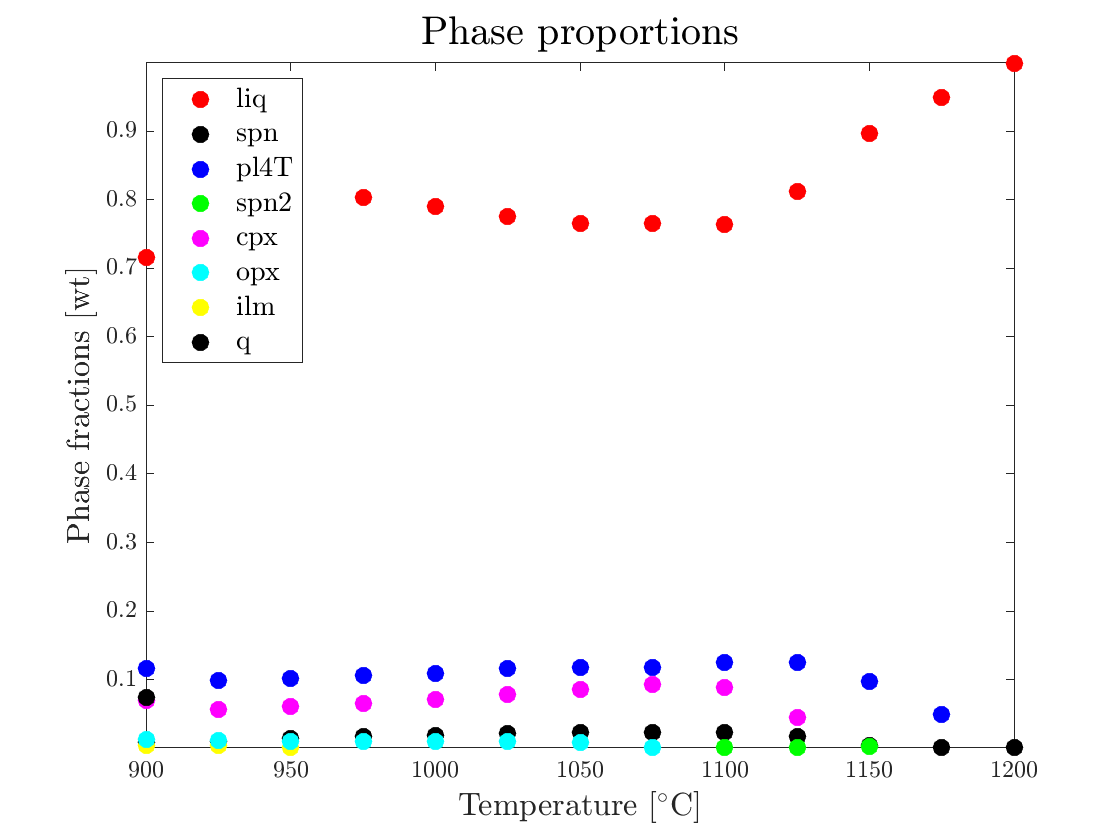

% prep phase colors
colors  = {'k' 'b' 'g' 'm' 'c' 'y' 'k' 'b' 'g' 'm' 'c' 'y'};
col.liq = 'r';
leg.liq = 'liq';
ic      = 1;

if isothermal
    xdata = OUT.P;
    xlbl = 'Pressure [kbar]';
elseif isobaric
    xdata = OUT.T;
    xlbl = 'Temperature [$^\circ$C]';
else
    xdata = OUT.T;
    xlbl = 'Temperature [$^\circ$C]';
end
    
% plot phase proportions
fig1 = figure(1); clf;
for ip=Points
    for is=1:OUT.numStablePhases(ip)
        phs = OUT.StablePhases{ip,is};
        if ~isfield(col,phs); col.(phs) = colors{ic}; ic = ic+1; end
        if ~isfield(leg,phs); leg.(phs) = phs; end
        p.(phs) = plot(xdata(ip),OUT.PhaseProps.(phs)(ip,1),'.','Color',col.(phs),'MarkerSize',30,'LineWidth',2.0); axis tight; box on; hold on;
    end
end
set(gca,'TickLabelInterpreter','latex','FontSize',12)
title('Phase proportions','Interpreter','latex','FontSize',20)
xlabel(xlbl,'Interpreter','latex','FontSize',16)
ylabel('Phase fractions [wt]','Interpreter','latex','FontSize',16)
pc   = struct2cell(p);
legc = struct2cell(leg);
legend([pc{:}],legc,'box','on','Interpreter','latex','FontSize',14,'Location','NorthWest')

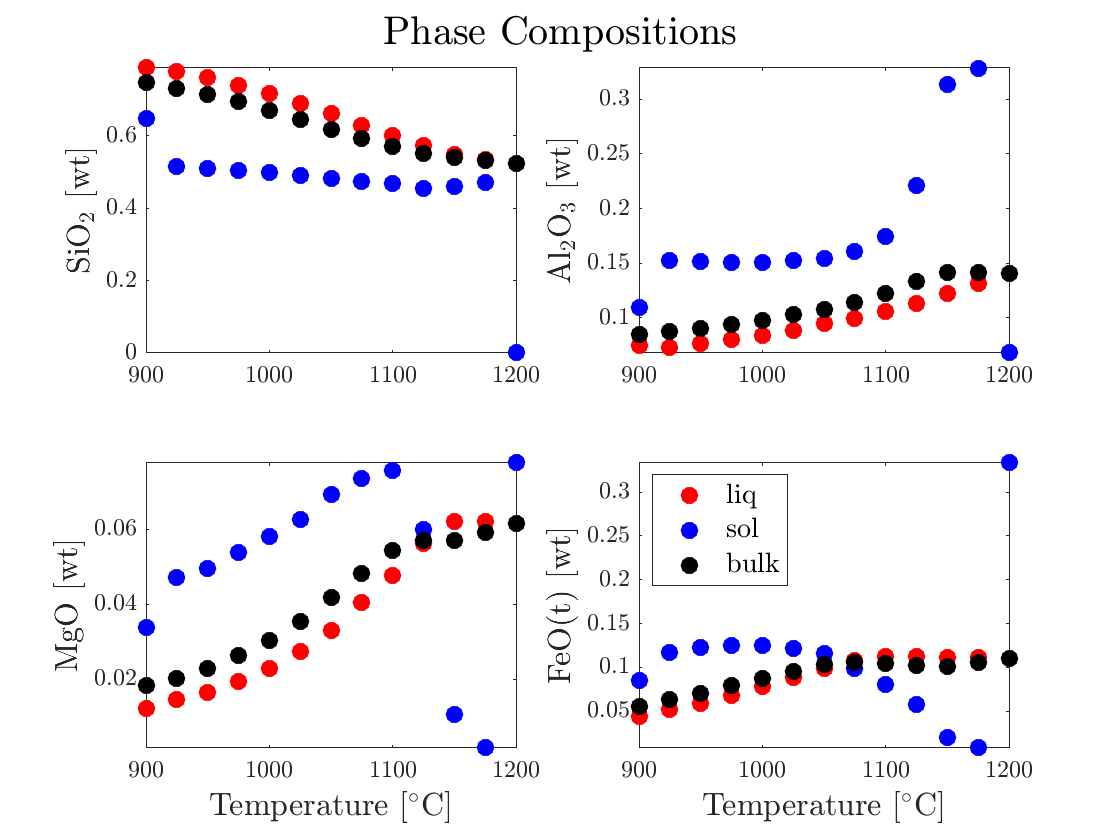

drawnow

% plot phase and system compositions
fig2 = figure(2); clf;
subplot(2,2,1)  % SiO2
pliq = plot(xdata,OUT.OxideFractions.liq(:,1),'r.','MarkerSize',30,'LineWidth',2.0); axis tight; box on; hold on;
psol = plot(xdata,OUT.OxideFractions.sol(:,1),'b.','MarkerSize',30,'LineWidth',2.0);
psys = plot(xdata,OUT.OxideFractions.SYS(:,1),'k.','MarkerSize',30,'LineWidth',2.0);
set(gca,'TickLabelInterpreter','latex','FontSize',12)
sgtitle('Phase Compositions','Interpreter','latex','FontSize',20)
ylabel('SiO$_2$ [wt]','Interpreter','latex','FontSize',16)

subplot(2,2,2)  % Al2O3
pliq = plot(xdata,OUT.OxideFractions.liq(:,2),'r.','MarkerSize',30,'LineWidth',2.0); axis tight; box on; hold on;
psol = plot(xdata,OUT.OxideFractions.sol(:,2),'b.','MarkerSize',30,'LineWidth',2.0);
psys = plot(xdata,OUT.OxideFractions.SYS(:,2),'k.','MarkerSize',30,'LineWidth',2.0);
set(gca,'TickLabelInterpreter','latex','FontSize',12)
ylabel('Al$_2$O$_3$ [wt]','Interpreter','latex','FontSize',16)

subplot(2,2,3)  % MgO
pliq = plot(xdata,OUT.OxideFractions.liq(:,4),'r.','MarkerSize',30,'LineWidth',2.0); axis tight; box on; hold on;
psol = plot(xdata,OUT.OxideFractions.sol(:,4),'b.','MarkerSize',30,'LineWidth',2.0);
psys = plot(xdata,OUT.OxideFractions.SYS(:,4),'k.','MarkerSize',30,'LineWidth',2.0);
set(gca,'TickLabelInterpreter','latex','FontSize',12)
xlabel(xlbl,'Interpreter','latex','FontSize',16)
ylabel('MgO [wt]','Interpreter','latex','FontSize',16)

subplot(2,2,4)  % FeO(t)
pliq = plot(xdata,OUT.OxideFractions.liq(:,5),'r.','MarkerSize',30,'LineWidth',2.0); axis tight; box on; hold on;
psol = plot(xdata,OUT.OxideFractions.sol(:,5),'b.','MarkerSize',30,'LineWidth',2.0);
psys = plot(xdata,OUT.OxideFractions.SYS(:,5),'k.','MarkerSize',30,'LineWidth',2.0);
set(gca,'TickLabelInterpreter','latex','FontSize',12)
xlabel(xlbl,'Interpreter','latex','FontSize',16)
ylabel('FeO(t) [wt]','Interpreter','latex','FontSize',16)
legend([pliq,psol,psys],{'liq','sol','bulk'},'box','on','Interpreter','latex','FontSize',14,'Location','NorthWest')

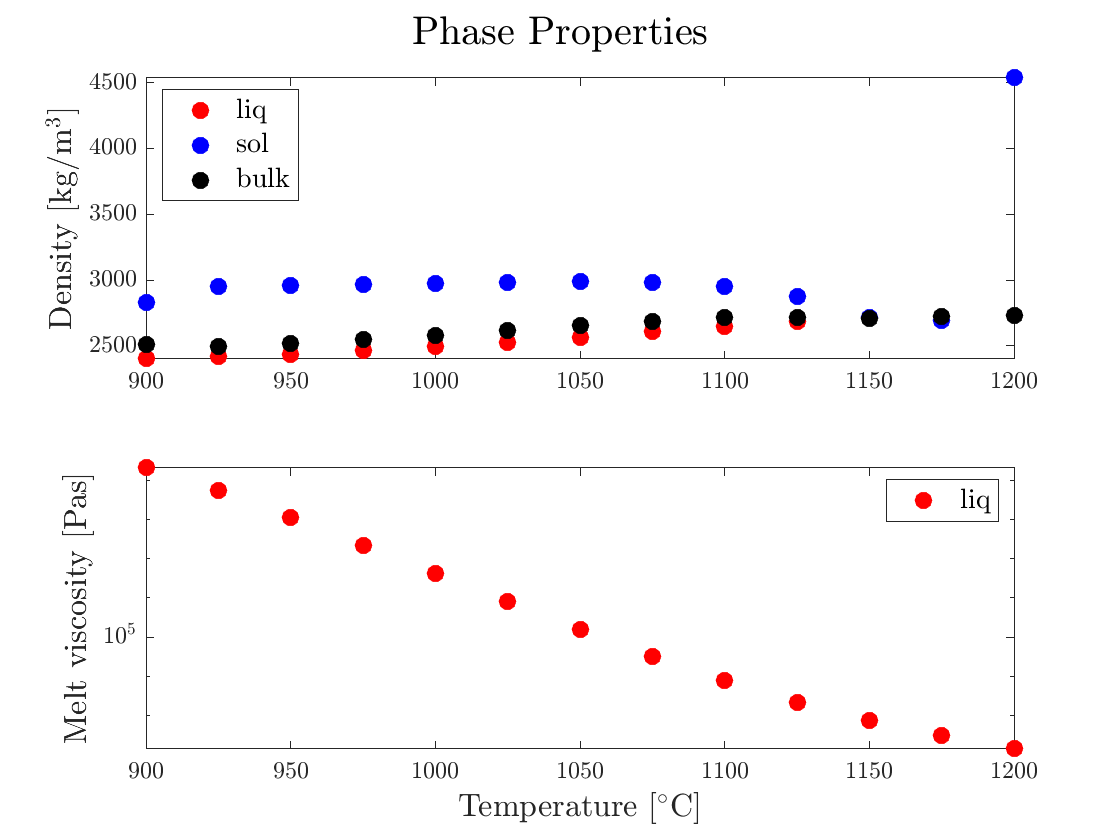

drawnow

% plot phase and system densities, melt viscosity
fig3 = figure(3); clf;
subplot(2,1,1);
pliq = plot(xdata,OUT.Density.liq,'r.','MarkerSize',30,'LineWidth',2.0); axis tight; box on; hold on;
psol = plot(xdata,OUT.Density.sol,'b.','MarkerSize',30,'LineWidth',2.0);
psys = plot(xdata,OUT.Density.SYS,'k.','MarkerSize',30,'LineWidth',2.0);
set(gca,'TickLabelInterpreter','latex','FontSize',12)
sgtitle('Phase Properties','Interpreter','latex','FontSize',20)
ylabel('Density [kg/m$^3$]','Interpreter','latex','FontSize',16)
legend([pliq,psol,psys],{'liq','sol','bulk'},'box','on','Interpreter','latex','FontSize',14,'Location','NorthWest')

% plot melt viscosity
subplot(2,1,2)
pliq = semilogy(xdata,OUT.Viscosity.liq,'r.','MarkerSize',30,'LineWidth',2.0); axis tight; box on; hold on;
set(gca,'TickLabelInterpreter','latex','FontSize',12)
xlabel(xlbl,'Interpreter','latex','FontSize',16)
ylabel('Melt viscosity [Pas]','Interpreter','latex','FontSize',16)
legend(pliq,'liq','box','on','Interpreter','latex','FontSize',14)

drawnow
